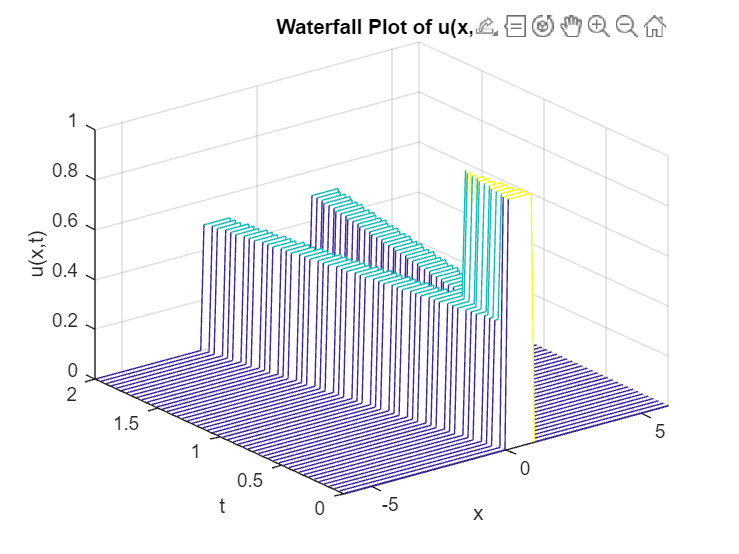

% Parameters
A = 1;
c = 1;

% Define the intervals
x = linspace(-6, 6, 100); % 100 points from -6 to 6
t = linspace(0, 2, 50);   % 50 points from 0 to 2

% Create a meshgrid for x and t
[X, T] = meshgrid(x, t);

% Heaviside function definition
H = @(z) (z >= 0); % Heaviside function

% Calculate u(x,t)
U = (A/2) * (-H(X - c*T - 1) + H(X - c*T) - H(X + c*T - 1) + H(X + c*T));

% Create a waterfall plot
figure;
waterfall(X, T, U);
xlabel('x');
ylabel('t');
zlabel('u(x,t)');
title('Waterfall Plot of u(x,t)');
grid on;